# Comparison with Current Protocols

format shortG
rng(0)
rawfoldincs = readmatrix("rawfoldincs.txt");
rawfoldincs(:,15:end)=[]

rawfoldincs =             1            1            1            1            1            1            1            1            1            1            1            1            1            1
        1.078         1.53        1.358        1.548        1.052        1.052         0.94        0.718       1.0855         1.19        1.131       1.5582        1.952       1.1377
       6.1224       4.6158       4.2724       6.3406        5.555        5.555       6.1277       6.0724        4.147       5.0623       4.6189       3.9479       4.8302       4.2567
       5.4756       4.7525        3.882        3.027          4.5          4.5       3.2186       3.4439       4.1462       6.0479       4.0482       5.3647       6.5694       3.4422
          NaN       2.3012       1.6283       1.3062       2.5181       2.5181       3.6119       2.2886       3.4762       4.1757       2.3177       2.2001       2.0197       2.5865
          NaN          NaN       1.3772       1.2429          NaN      

conforplot =           0.1            0
          0.1            0
       0.1078            3
      0.03234            3
        0.198            5
        0.198            5
       1.0842            7
      0.19515            7
          NaN            9
          NaN            9


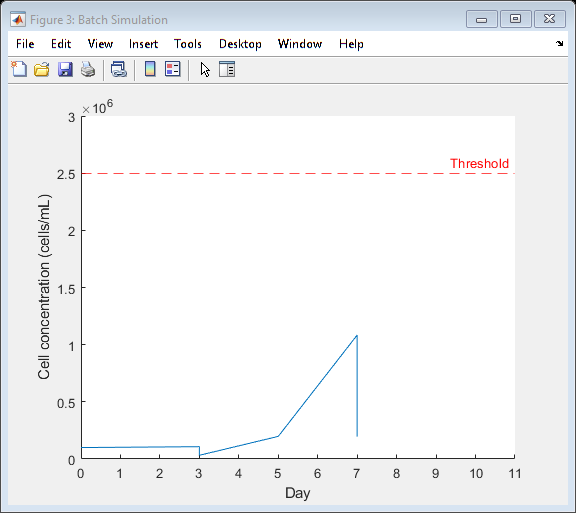

conforplot =           0.1            0
          0.1            0
        0.153            3
      0.02754            3
      0.12712            5
     0.026695            5
      0.12687            7
     0.034255            7
     0.078828            9
     0.078828            9


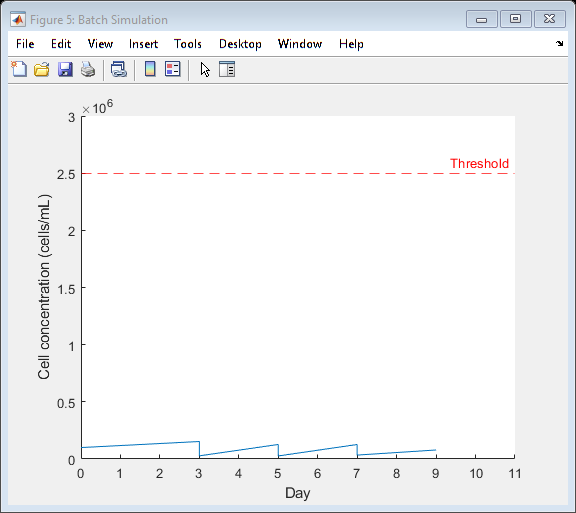

conforplot =           0.1            0
          0.1            0
       0.1358            3
     0.024444            3
      0.10443            5
      0.10443            5
      0.40541            7
      0.40541            7
      0.66015            9
      0.15843            9


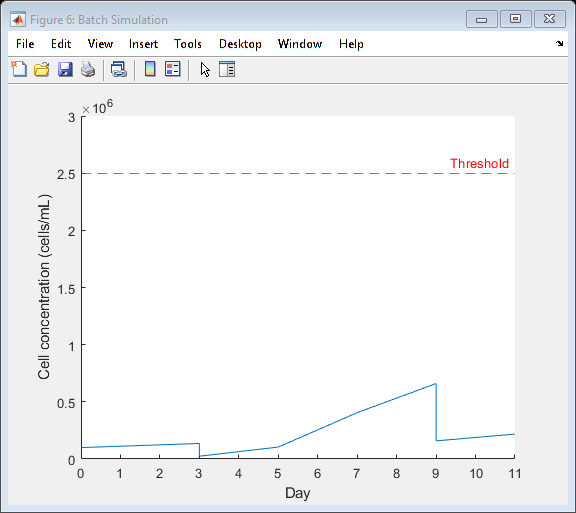

conforplot =           0.1            0
          0.1            0
       0.1548            3
     0.027864            3
      0.17667            5
     0.042402            5
      0.12835            7
      0.12835            7
      0.16765            9
     0.050294            9


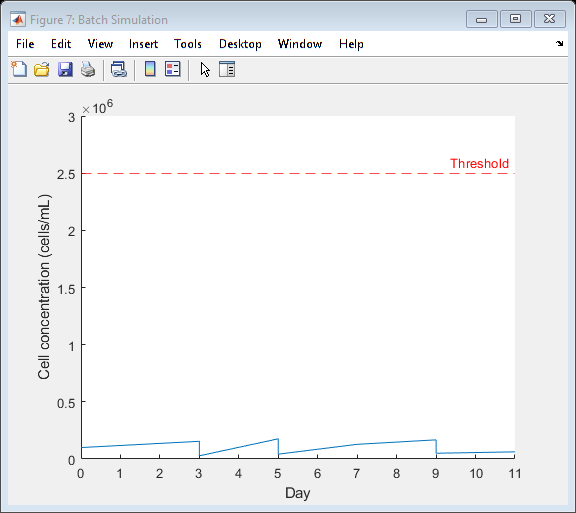

conforplot =           0.1            0
          0.1            0
       0.1052            3
     0.028404            3
      0.15778            5
     0.028401            5
      0.12781            7
      0.12781            7
      0.32182            9
      0.32182            9


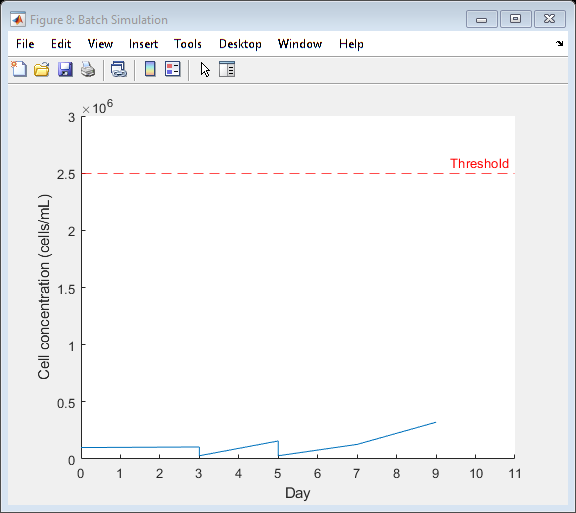

conforplot =           0.1            0
          0.1            0
       0.1052            3
      0.03156            3
      0.17532            5
     0.052595            5
      0.23668            7
     0.056803            7
      0.14303            9
     0.038619            9


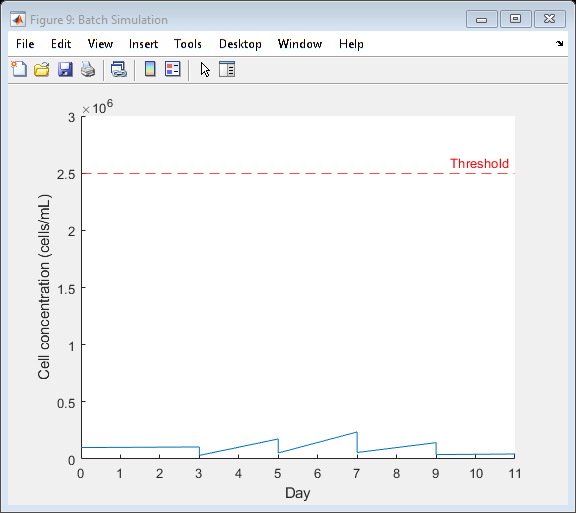

conforplot =           0.1            0
          0.1            0
        0.094            3
       0.0282            3
       0.1728            5
     0.031104            5
      0.10011            7
     0.021024            7
     0.075936            9
     0.013668            9


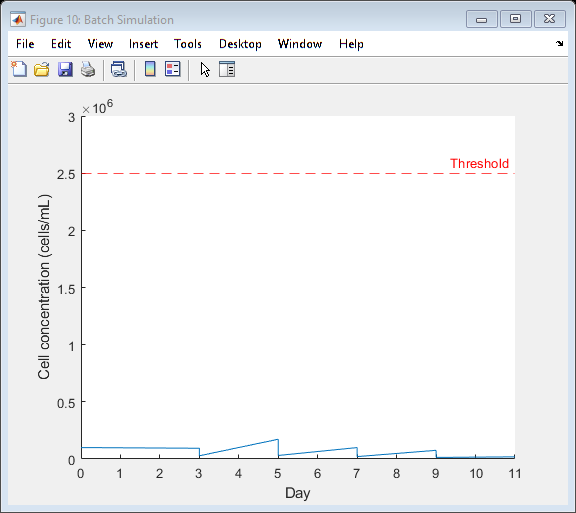

conforplot =           0.1            0
          0.1            0
       0.0718            3
      0.02154            3
       0.1308            5
      0.03924            5
      0.13514            7
     0.028379            7
     0.064949            9
     0.064949            9


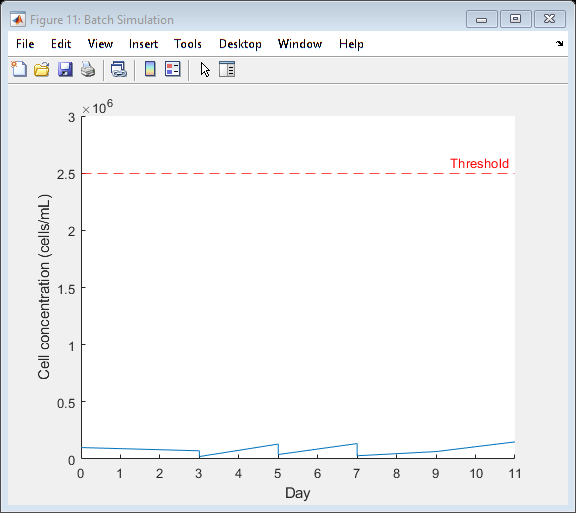

conforplot =           0.1            0
          0.1            0
      0.10855            3
     0.026051            3
      0.10803            5
     0.025928            5
       0.1075            7
     0.032251            7
      0.11211            9
     0.033633            9


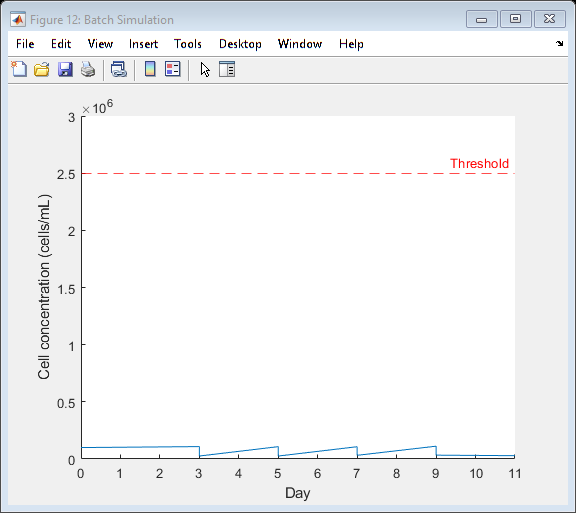

conforplot =           0.1            0
          0.1            0
        0.119            3
      0.02856            3
      0.14458            5
     0.034699            5
      0.20985            7
     0.056661            7
       0.2366            9
      0.07098            9


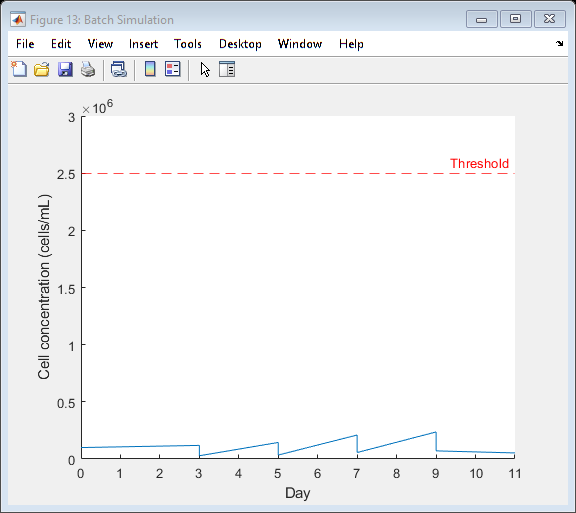

conforplot =           0.1            0
          0.1            0
       0.1131            3
     0.023751            3
       0.1097            5
      0.03291            5
      0.13323            7
     0.035971            7
     0.083372            9
     0.015007            9


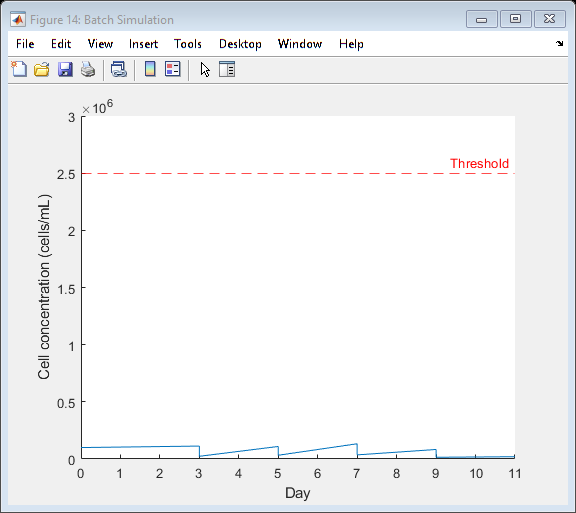

conforplot =           0.1            0
          0.1            0
      0.15582            3
     0.037396            3
      0.14764            5
      0.14764            5
      0.79202            7
      0.19009            7
       0.4182            9
      0.11291            9


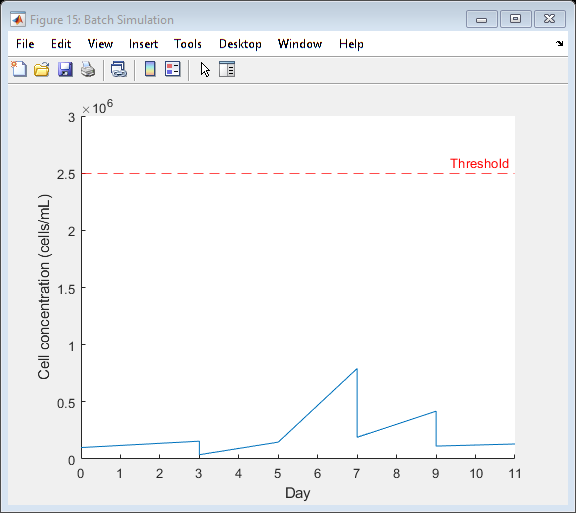

conforplot =           0.1            0
          0.1            0
       0.1952            3
      0.05856            3
      0.28286            5
       0.0594            5
      0.39022            7
      0.10536            7
      0.21279            9
     0.063838            9


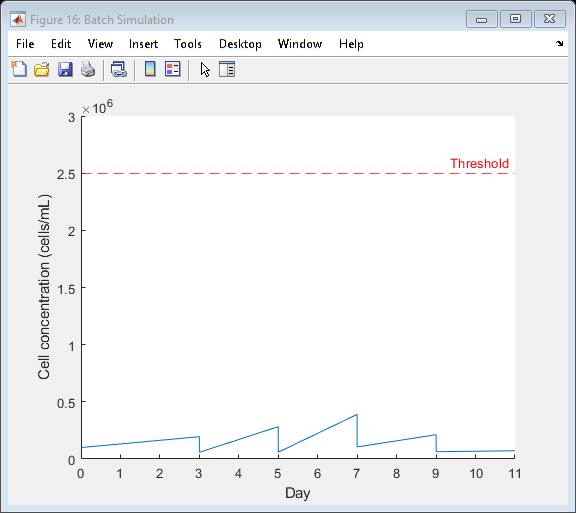

conforplot =           0.1            0
          0.1            0
      0.11377            3
      0.11377            3
      0.48429            5
      0.13076            5
       0.4501            7
     0.081018            7
      0.20955            9
      0.03772            9


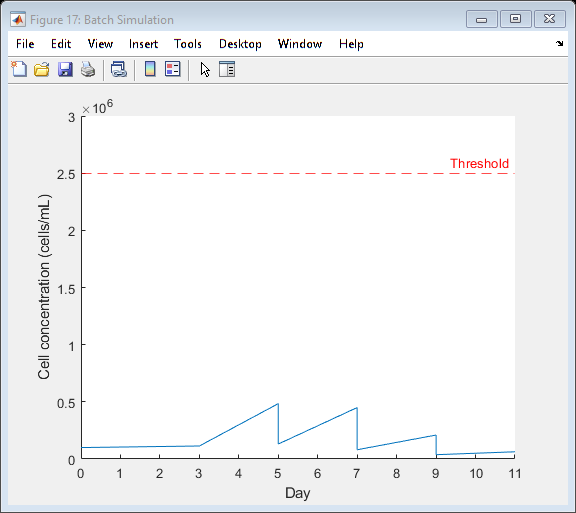

dilutecon = 0.5;
initstate = [0.1,1];
actions = [0.18, 0.21, 0.24, 0.27, 0.3, 1];
day = [0,3,5,7,9,11];
culturenum = 14;
concentrationThreshold = 2.5;
rewards = zeros(numel(culturenum));
simresults = zeros(size(rawfoldincs,1),culturenum);
Reward1=1;
Penalty1=-2.5;

for i=1:culturenum
    State=initstate;
    timeStep=0;
    timsStepStart=0;
    Reward=0;
    foldExMap = rawfoldincs(:,i);
    simresult = zeros(size(rawfoldincs,1),1);
    conforplot = [];
    for j=1:numel(day)
        if day(j)==0
            Action=1;
        else
            Action = actions(randi(numel(actions)));
        end
        
        if j==6
            conforplot = [conforplot; State]; 
        else
            [State,reward,conforplot]=step(State,Action,concentrationThreshold,foldExMap,Reward1,Penalty1,conforplot);
        end

        simresult(j) = State(1);
        if isfinite(reward)
            Reward = Reward + reward;
        end
    end
    
    for k=1:size(conforplot,1)
        conforplot(k,2)=day(conforplot(k,2));
    end
    conforplot
    rewards(i)=Reward;
    simresults(:,i) = simresult; 

    Figure = figure('Name','Batch Simulation','Visible','on','HandleVisibility','off');
    ha = gca(Figure);
    ha.XLimMode = 'manual';
    ha.YLimMode = 'manual';
    ha.XLim = [0,11];
    ha.YLim = [0,3000000];
    xlabel(ha,'Day')
    ylabel(ha,'Cell concentration (cells/mL)')
    ha.TitleHorizontalAlignment = 'right';
    clf;
    hold(ha,'on');
    yline(ha,2500000,'r--','Threshold')      
    ConcentrationPlot = plot(ha,conforplot(:,2),conforplot(:,1).*1000000,'LineStyle','-','Color',[0, 0.4470, 0.7410]);
end


rewards

rewards =         -1.11      -7.0142      -5.7578      -9.2475      -4.2874      -11.752      -12.019      -6.7979      -12.006      -11.684       -12.02      -8.2239      -11.275      -8.6162


simresults

simresults =        0.1078        0.153       0.1358       0.1548       0.1052       0.1052        0.094       0.0718      0.10855        0.119       0.1131      0.15582       0.1952      0.11377
        0.198      0.12712      0.10443      0.17667      0.15778      0.17532       0.1728       0.1308      0.10803      0.14458       0.1097      0.14764      0.28286      0.48429
       1.0842      0.12687      0.40541      0.12835      0.12781      0.23668      0.10011      0.13514       0.1075      0.20985      0.13323      0.79202      0.39022       0.4501
          NaN     0.078828      0.66015      0.16765      0.32182      0.14303     0.075936     0.064949      0.11211       0.2366     0.083372       0.4182      0.21279      0.20955
          NaN          NaN       0.2182     0.062511          NaN     0.043745     0.018865       0.1497     0.029133     0.053101     0.020081      0.13121     0.072016     0.063031
          NaN          NaN       0.2182     0.062511          NaN     0.

totalscorerandom = sum(rewards)

totalscorerandom =       -121.81


function [State,reward,conforplot] = step(State,Action,concentrationThreshold,foldExMap,Reward1,Penalty1,conforplot)
    
    % Unpack state vector
    state = State;
    con = state(1);
    time = state(2);
    
    conforplot = [conforplot; [con,time]];

    % Apply system dynamics        
    con = con.*Action;
        
    conforplot = [conforplot; [con,time]];

    % calculate next state values
    time = time + 1;
    con = con * foldExMap(time);
    
    if con>(concentrationThreshold)
        overthreshold = true;
    else 
        overthreshold = false;
    end
    
    % Update system states
    State = [con,time];

    % Get reward    
    if overthreshold == false
        reward = con*Reward1;
    else
        reward = 5*concentrationThreshold-4*con*Reward1;
    end
    
    if Action<1
        reward = reward + Penalty1;
    end           
end